## Blatt 6

clear;clc;

## Aufgabe 1


$$$\frac{\mathrm{d} \phi(t)}{\mathrm{d} t}=t^2 e^{-5 t}-6 \phi(t)$$$
 


$$$\phi(t)=e^{-5 t}\left(t^2-2 t+2\right)-2 e^{-6 t}$$$


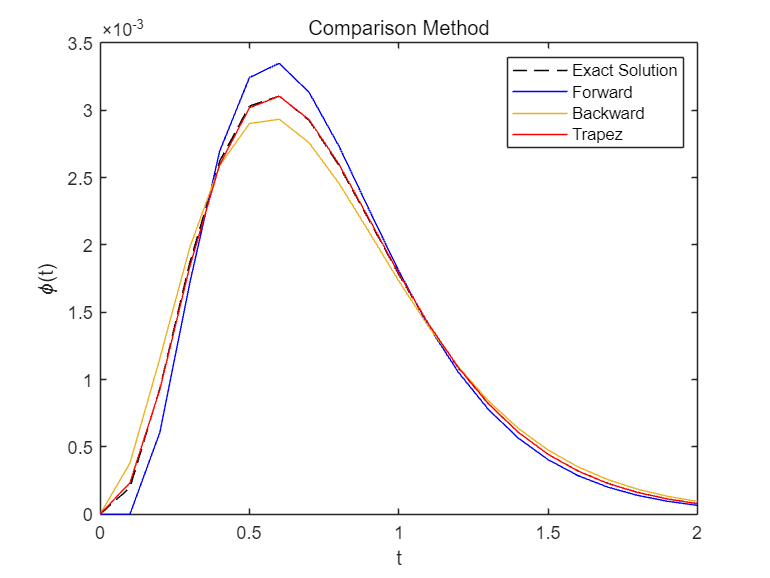

% Parameter setting

theta=[0,1,1/2];
% Vorwärts-Euler Verfahren
t0=0:0.1:2;
phi_exact=exactSolution(t0);
phi_forward=forwardEuler(0,2,0.1);
phi_backward=backwardEuler(0,2,0.1);    
phi_trapez=trapezEuler(0,2,0.1);  
figure
% Exact
plot(t0, phi_exact, '--k','DisplayName','Exact Solution'); 
hold on;

% Foreward
plot(t0, phi_forward, '-blue','DisplayName','Forward'); 
hold on; % 保持当前图像，以便在相同的坐标轴上绘制第二组数据

% Backward
plot(t0, phi_backward, 'LineStyle', '-', 'Color', [0.9290 0.6940 0.1250],'DisplayName','Backward');
hold on;

% Trapez
plot(t0, phi_trapez, '-r','DisplayName','Trapez');
hold off; % 关闭保持状态

% 添加图例和坐标轴标签等
legend;
xlabel('t');
ylabel('\phi(t)');
title('Comparison Method');

## Aufgabe 2

d=3

d = 3

## Funktion

### Funktion


$$\frac{\mathrm{d} \phi(t)}{\mathrm{d} t}=f(t, \phi(t))
\\
\frac{\mathrm{d} \phi(t)}{\mathrm{d} t}=t^2 e^{-5 t}-6 \phi(t)$$


其中，令$g\left(t\right)=t^2 e^{-5t}$ 方便后续的简化计算

function g=g(t)
g=t^2 * exp(-5*t);
end
function dphi = odeFun(t, phi)
    dphi = g(t) - 6*phi;
end

function phi = exactSolution(t)
    phi = exp(-5*t) .* (t.^2 - 2*t + 2) - 2*exp(-6*t);
end

## Vorward Euler

function phi_forward = forwardEuler(t_start, t_end, delta_t)
    t = t_start:delta_t:t_end;
    len = length(t);
    phi = zeros(1, len);
    for n = 1:len-1
        phi(n+1) = phi(n) + delta_t * (g(t(n)) - 6*phi(n));
    end
    phi_forward = phi;
end

## Backward Euler

function  phi_backward=backwardEuler(t_start, t_end, delta_t)
    t = t_start:delta_t:t_end;
    len = length(t);
    phi = zeros(1, len);
    for n=1:len-1
        % n 是数组循环的index,整数，从1到20，不是时间
        % t(n)是时间范围0到2之间的第n个时间
        % 例如在第二次迭代(n=2)时，t应该等于0+0.1*2=0.2s，对应t(n)
        % 区分到底 g(n+1)还是g(t(n+1))
        phi(n+1) = (phi(n)+delta_t*g(t(n+1)))/(1+delta_t*6);% 1+delta_t*6 是简化公式得来的，
        % 这也是为什么没有用odefunc这个函数，而是使用g(t)*一个东西
    end
    phi_backward=phi;
end

## Trapez Euler

function  phi_backward=trapezEuler(t_start, t_end, delta_t)
    t = t_start:delta_t:t_end;
    len = length(t);
    phi = zeros(1, len);
    for n=1:len-1
        % 公式推导见Notability
        phi(n+1) = ((1-3*delta_t)*phi(n)+0.5*delta_t*(g(t(n))+g(t(n+1))))/(1+3*delta_t);
    end
    phi_backward=phi;
end

allgemein Form:


$$$\phi_{n+1}=\phi_n+\theta \Delta t f\left(t_{n+1}, \phi_{n+1}\right)+(1-\theta) \Delta t f\left(t_n, \phi_n\right)$$$


function next_phi=cal_phi(phi,theta,timestep)
end

### Fkt. 9

### Fkt. 10